%% resultados_base_figuras_memoria_v2.m
% Figuras mejoradas de los casos base para la memoria
%
% Casos:
%   - Caso A: viento constante 16 m/s
%   - Caso B: viento turbulento 16 m/s
%
% Ventana de análisis:
%   t >= 500 s
%
% Salidas:
%   Resultados/Figuras_Memoria/Base_v2

clear; clc; close all;

%% Rutas

rootDir = fullfile(getenv('USERPROFILE'), 'Desktop', 'TFM_OpenFast');

matlabDir = fullfile(rootDir, 'Matlab');
addpath(genpath(matlabDir));

if isempty(which('ReadFASTbinary'))

    d = dir(fullfile(rootDir, '**', 'ReadFASTbinary.m'));

    if isempty(d)
        error('No se encuentra ReadFASTbinary.m dentro de TFM_OpenFast.');
    else
        addpath(genpath(d(1).folder));
        fprintf('ReadFASTbinary añadido desde:\n%s\n', fullfile(d(1).folder, d(1).name));
    end
end

outFigDir = fullfile(rootDir, 'Resultados', 'Figuras_Memoria', 'Base_v2');

if ~exist(outFigDir, 'dir')
    mkdir(outFigDir);
end

%% Configuración general de análisis

tTrans = 500;
tZoom  = [500 620];

mDEL   = 10;
NeqDEL = 1e6;   % Importante: usar el mismo Neq que en las comparativas finales

%% Casos base

casos = struct([]);

casos(1).nombre = "Caso A - viento constante";
casos(1).tag = "CasoA_v16_constante";
casos(1).dir = fullfile(rootDir, 'Resultados', 'CasoA_v16_constante');

casos(2).nombre = "Caso B - viento turbulento";
casos(2).tag = "CasoB_v16_turbulento";
casos(2).dir = fullfile(rootDir, 'Resultados', 'CasoB_v16_turbulento');

%% Localizar archivos .outb

for i = 1:numel(casos)

    if exist(casos(i).dir, 'dir')
        d = dir(fullfile(casos(i).dir, '**', '*.outb'));
    else
        d = [];
    end

    if isempty(d)
        dAll = dir(fullfile(rootDir, 'Resultados', '**', '*.outb'));

        idx = contains(lower({dAll.folder}), lower(casos(i).tag)) | ...
              contains(lower({dAll.name}), lower(casos(i).tag));

        d = dAll(idx);
    end

    if isempty(d)
        error('No se encuentra archivo .outb para %s', casos(i).nombre);
    end

    casos(i).outb = fullfile(d(1).folder, d(1).name);

    fprintf('\n%s\n%s\n', casos(i).nombre, casos(i).outb);
end


Caso A - viento constante
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb

Caso B - viento turbulento
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb



%% Lectura de señales

for i = 1:numel(casos)

    tmp = leerCasoOpenFAST(casos(i).outb, casos(i).nombre, tTrans);

    if i == 1
        S = repmat(tmp, numel(casos), 1);
    else
        tmp = orderfields(tmp, S(1));
        S(i) = tmp;
    end
end

Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 11-Aug-2026 at 18:11:56 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".
Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 11-Aug-2026 at 19:18:39 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 20


%% Tabla resumen

tablaBase = table();

for i = 1:numel(S)

    fila = table();

    fila.Caso = string(S(i).nombre);
    fila.Tiempo_analisis_s = max(S(i).t) - min(S(i).t);

    fila.Mean_GenPwr_MW = mean(S(i).GenPwr_MW, 'omitnan');
    fila.Std_GenPwr_MW  = std(S(i).GenPwr_MW, 'omitnan');

    fila.Mean_RotSpeed_rpm = mean(S(i).RotSpeed_rpm, 'omitnan');
    fila.Std_RotSpeed_rpm  = std(S(i).RotSpeed_rpm, 'omitnan');

    fila.Mean_BldPitch_deg = mean(S(i).BldPitchMean_deg, 'omitnan');
    fila.Std_BldPitch_deg  = std(S(i).BldPitchMean_deg, 'omitnan');

    fila.RMS_PtfmPitch_deg = rmsDemean(S(i).PtfmPitch_deg);
    fila.RMS_PtfmSurge_m   = rmsDemean(S(i).PtfmSurge_m);

    fila.DEL_RootMyb1_MNm = calcDEL(S(i).RootMyb1_MNm, mDEL, NeqDEL);
    fila.DEL_RootMyb2_MNm = calcDEL(S(i).RootMyb2_MNm, mDEL, NeqDEL);
    fila.DEL_RootMyb3_MNm = calcDEL(S(i).RootMyb3_MNm, mDEL, NeqDEL);

    fila.DEL_RootMyb_mean_MNm = mean([ ...
        fila.DEL_RootMyb1_MNm, ...
        fila.DEL_RootMyb2_MNm, ...
        fila.DEL_RootMyb3_MNm], 'omitnan');

    fila.RMS_Mtilt_MNm = rmsDemean(S(i).Mtilt_MNm);
    fila.RMS_Myaw_MNm  = rmsDemean(S(i).Myaw_MNm);

    tablaBase = [tablaBase; fila];
end

disp(tablaBase);

                Caso                Tiempo_analisis_s    Mean_GenPwr_MW    Std_GenPwr_MW    Mean_RotSpeed_rpm    Std_RotSpeed_rpm    Mean_BldPitch_deg    Std_BldPitch_deg    RMS_PtfmPitch_deg    RMS_PtfmSurge_m    DEL_RootMyb1_MNm    DEL_RootMyb2_MNm    DEL_RootMyb3_MNm    DEL_RootMyb_mean_MNm    RMS_Mtilt_MNm    RMS_Myaw_MNm
    ____________________________    _________________    ______________    _____________    _________________    ________________    _________________    ________________    _________________    _______________    ________

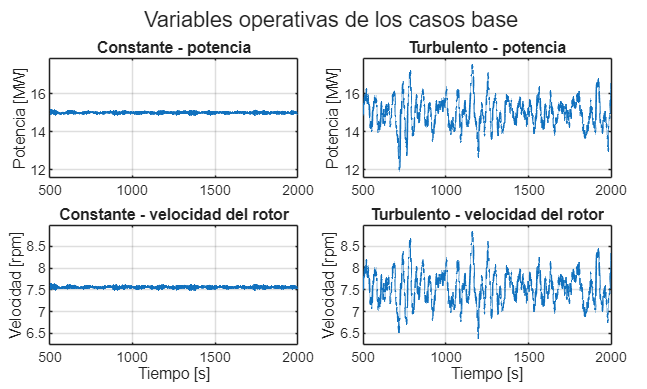


writetable(tablaBase, fullfile(outFigDir, 'tabla_metricas_base_v2.xlsx'));

%% Ajustes gráficos generales

set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);
set(groot, 'defaultLegendFontSize', 11);

%% ============================================================
% FIGURA 1: variables operativas
% Potencia y velocidad del rotor
% ============================================================

fig = figure('Color','w','Position',[100 100 1250 750]);
tl = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

ax = gobjects(4,1);

ax(1) = nexttile;
plot(S(1).t, S(1).GenPwr_MW, 'LineWidth', 1.0);
grid on; box on;
title('Constante - potencia');
ylabel('Potencia [MW]');
xlim([tTrans max(S(1).t)]);

ax(2) = nexttile;
plot(S(2).t, S(2).GenPwr_MW, 'LineWidth', 1.0);
grid on; box on;
title('Turbulento - potencia');
ylabel('Potencia [MW]');
xlim([tTrans max(S(2).t)]);

ax(3) = nexttile;
plot(S(1).t, S(1).RotSpeed_rpm, 'LineWidth', 1.0);
grid on; box on;
title('Constante - velocidad del rotor');
ylabel('Velocidad [rpm]');
xlabel('Tiempo [s]');
xlim([tTrans max(S(1).t)]);

ax(4) = nexttile;
plot(S(2).t, S(2).RotSpeed_rpm, 'LineWidth', 1.0);
grid on; box on;
title('Turbulento - velocidad del rotor');
ylabel('Velocidad [rpm]');
xlabel('Tiempo [s]');
xlim([tTrans max(S(2).t)]);

ylimP = paddedLim([S(1).GenPwr_MW; S(2).GenPwr_MW], 0.06);
ylimR = paddedLim([S(1).RotSpeed_rpm; S(2).RotSpeed_rpm], 0.06);

set(ax(1:2), 'YLim', ylimP);
set(ax(3:4), 'YLim', ylimR);

title(tl, 'Variables operativas de los casos base');

guardarFigura(fig, outFigDir, 'base_v2_variables_operativas');

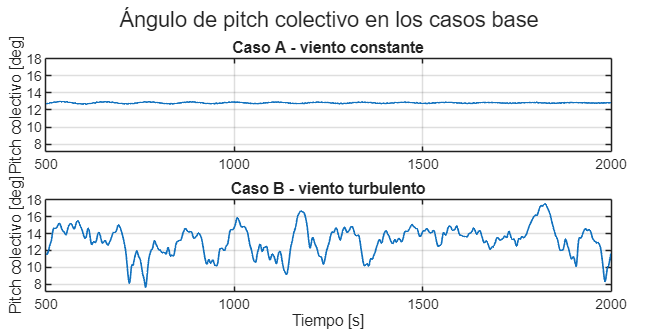


%% ============================================================
% FIGURA 2: pitch colectivo
% ============================================================

fig = figure('Color','w','Position',[100 100 1250 650]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

ax = gobjects(2,1);

ax(1) = nexttile;
plot(S(1).t, S(1).BldPitchMean_deg, 'LineWidth', 1.0);
grid on; box on;
title('Caso A - viento constante');
ylabel('Pitch colectivo [deg]');
xlim([tTrans max(S(1).t)]);

ax(2) = nexttile;
plot(S(2).t, S(2).BldPitchMean_deg, 'LineWidth', 1.0);
grid on; box on;
title('Caso B - viento turbulento');
ylabel('Pitch colectivo [deg]');
xlabel('Tiempo [s]');
xlim([tTrans max(S(2).t)]);

ylimPitch = paddedLim([S(1).BldPitchMean_deg; S(2).BldPitchMean_deg], 0.06);
set(ax, 'YLim', ylimPitch);

title(tl, 'Ángulo de pitch colectivo en los casos base');

guardarFigura(fig, outFigDir, 'base_v2_pitch_colectivo');

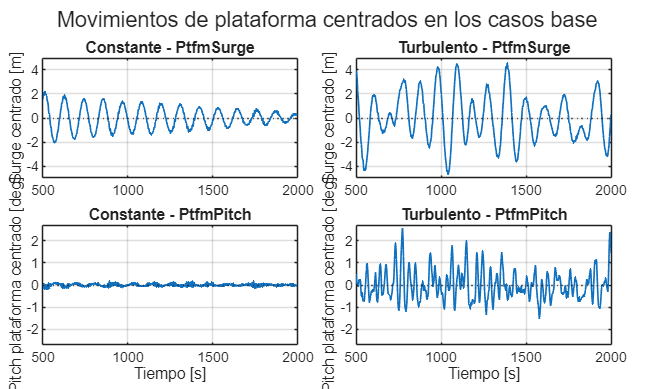


%% ============================================================
% FIGURA 3: movimientos de plataforma centrados
% ============================================================

surge1 = demeanSignal(S(1).PtfmSurge_m);
surge2 = demeanSignal(S(2).PtfmSurge_m);

pitchPtfm1 = demeanSignal(S(1).PtfmPitch_deg);
pitchPtfm2 = demeanSignal(S(2).PtfmPitch_deg);

fig = figure('Color','w','Position',[100 100 1250 750]);
tl = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

ax = gobjects(4,1);

ax(1) = nexttile;
plot(S(1).t, surge1, 'LineWidth', 1.0);
grid on; box on;
title('Constante - PtfmSurge');
ylabel('Surge centrado [m]');
xlim([tTrans max(S(1).t)]);
yline(0, ':');

ax(2) = nexttile;
plot(S(2).t, surge2, 'LineWidth', 1.0);
grid on; box on;
title('Turbulento - PtfmSurge');
ylabel('Surge centrado [m]');
xlim([tTrans max(S(2).t)]);
yline(0, ':');

ax(3) = nexttile;
plot(S(1).t, pitchPtfm1, 'LineWidth', 1.0);
grid on; box on;
title('Constante - PtfmPitch');
ylabel('Pitch plataforma centrado [deg]');
xlabel('Tiempo [s]');
xlim([tTrans max(S(1).t)]);
yline(0, ':');

ax(4) = nexttile;
plot(S(2).t, pitchPtfm2, 'LineWidth', 1.0);
grid on; box on;
title('Turbulento - PtfmPitch');
ylabel('Pitch plataforma centrado [deg]');
xlabel('Tiempo [s]');
xlim([tTrans max(S(2).t)]);
yline(0, ':');

ylimSurge = symmetricLim([surge1; surge2], 0.06);
ylimPtfmPitch = symmetricLim([pitchPtfm1; pitchPtfm2], 0.06);

set(ax(1:2), 'YLim', ylimSurge);
set(ax(3:4), 'YLim', ylimPtfmPitch);

title(tl, 'Movimientos de plataforma centrados en los casos base');

guardarFigura(fig, outFigDir, 'base_v2_plataforma_centrada');

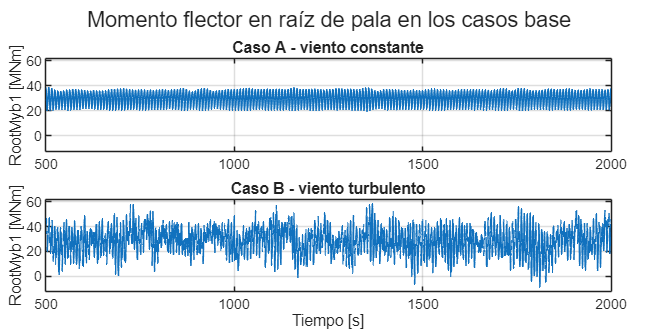


%% ============================================================
% FIGURA 4: RootMyb1 global
% ============================================================

fig = figure('Color','w','Position',[100 100 1250 650]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

ax = gobjects(2,1);

ax(1) = nexttile;
plot(S(1).t, S(1).RootMyb1_MNm, 'LineWidth', 0.9);
grid on; box on;
title('Caso A - viento constante');
ylabel('RootMyb1 [MNm]');
xlim([tTrans max(S(1).t)]);

ax(2) = nexttile;
plot(S(2).t, S(2).RootMyb1_MNm, 'LineWidth', 0.9);
grid on; box on;
title('Caso B - viento turbulento');
ylabel('RootMyb1 [MNm]');
xlabel('Tiempo [s]');
xlim([tTrans max(S(2).t)]);

ylimRoot = paddedLim([S(1).RootMyb1_MNm; S(2).RootMyb1_MNm], 0.06);
set(ax, 'YLim', ylimRoot);

title(tl, 'Momento flector en raíz de pala en los casos base');

guardarFigura(fig, outFigDir, 'base_v2_rootmyb1_global');

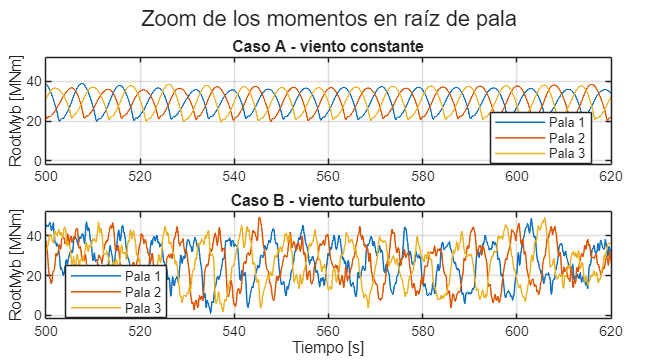


%% ============================================================
% FIGURA 5: zoom RootMyb de las tres palas
% ============================================================

fig = figure('Color','w','Position',[100 100 1250 700]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

ax = gobjects(2,1);

for i = 1:numel(S)

    idxZoom = S(i).t >= tZoom(1) & S(i).t <= tZoom(2);

    ax(i) = nexttile;

    plot(S(i).t(idxZoom), S(i).RootMyb1_MNm(idxZoom), 'LineWidth', 0.9); hold on;
    plot(S(i).t(idxZoom), S(i).RootMyb2_MNm(idxZoom), 'LineWidth', 0.9);
    plot(S(i).t(idxZoom), S(i).RootMyb3_MNm(idxZoom), 'LineWidth', 0.9);

    grid on; box on;
    title(S(i).nombre);
    ylabel('RootMyb [MNm]');
    xlim(tZoom);

    legend('Pala 1','Pala 2','Pala 3','Location','best');
end

xlabel('Tiempo [s]');

ylimZoom = paddedLim([ ...
    S(1).RootMyb1_MNm(S(1).t >= tZoom(1) & S(1).t <= tZoom(2)); ...
    S(1).RootMyb2_MNm(S(1).t >= tZoom(1) & S(1).t <= tZoom(2)); ...
    S(1).RootMyb3_MNm(S(1).t >= tZoom(1) & S(1).t <= tZoom(2)); ...
    S(2).RootMyb1_MNm(S(2).t >= tZoom(1) & S(2).t <= tZoom(2)); ...
    S(2).RootMyb2_MNm(S(2).t >= tZoom(1) & S(2).t <= tZoom(2)); ...
    S(2).RootMyb3_MNm(S(2).t >= tZoom(1) & S(2).t <= tZoom(2))], 0.06);

set(ax, 'YLim', ylimZoom);

title(tl, 'Zoom de los momentos en raíz de pala');

guardarFigura(fig, outFigDir, 'base_v2_rootmyb_zoom_3palas');

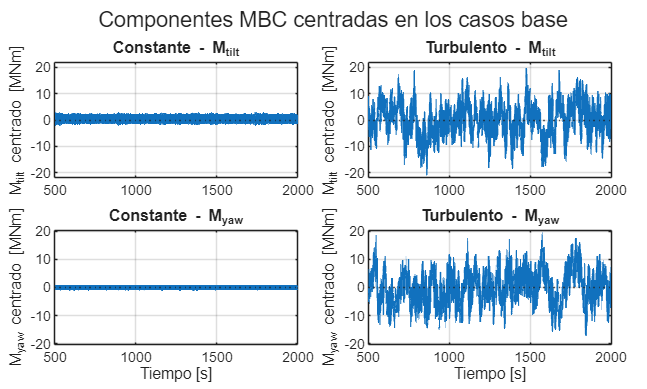


%% ============================================================
% FIGURA 6: componentes MBC centradas
% ============================================================

mtilt1 = demeanSignal(S(1).Mtilt_MNm);
mtilt2 = demeanSignal(S(2).Mtilt_MNm);

myaw1 = demeanSignal(S(1).Myaw_MNm);
myaw2 = demeanSignal(S(2).Myaw_MNm);

fig = figure('Color','w','Position',[100 100 1250 750]);
tl = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

ax = gobjects(4,1);

ax(1) = nexttile;
plot(S(1).t, mtilt1, 'LineWidth', 1.0);
grid on; box on;
title('Constante - M_{tilt}');
ylabel('M_{tilt} centrado [MNm]');
xlim([tTrans max(S(1).t)]);
yline(0, ':');

ax(2) = nexttile;
plot(S(2).t, mtilt2, 'LineWidth', 1.0);
grid on; box on;
title('Turbulento - M_{tilt}');
ylabel('M_{tilt} centrado [MNm]');
xlim([tTrans max(S(2).t)]);
yline(0, ':');

ax(3) = nexttile;
plot(S(1).t, myaw1, 'LineWidth', 1.0);
grid on; box on;
title('Constante - M_{yaw}');
ylabel('M_{yaw} centrado [MNm]');
xlabel('Tiempo [s]');
xlim([tTrans max(S(1).t)]);
yline(0, ':');

ax(4) = nexttile;
plot(S(2).t, myaw2, 'LineWidth', 1.0);
grid on; box on;
title('Turbulento - M_{yaw}');
ylabel('M_{yaw} centrado [MNm]');
xlabel('Tiempo [s]');
xlim([tTrans max(S(2).t)]);
yline(0, ':');

ylimTilt = symmetricLim([mtilt1; mtilt2], 0.06);
ylimYaw  = symmetricLim([myaw1; myaw2], 0.06);

set(ax(1:2), 'YLim', ylimTilt);
set(ax(3:4), 'YLim', ylimYaw);

title(tl, 'Componentes MBC centradas en los casos base');

guardarFigura(fig, outFigDir, 'base_v2_mbc_centrado');

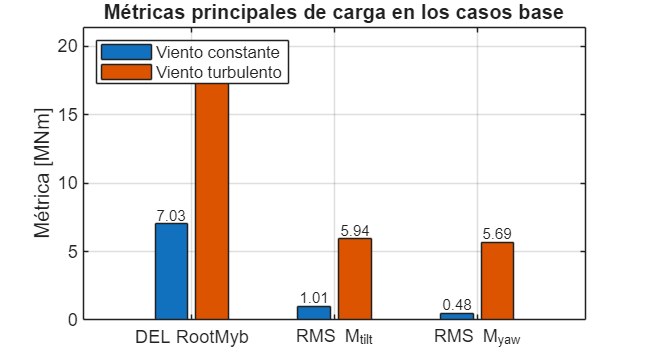


%% ============================================================
% FIGURA 7: barras de métricas de carga - versión limpia
% ============================================================

metricsCarga = categorical({'DEL RootMyb','RMS M_{tilt}','RMS M_{yaw}'});
metricsCarga = reordercats(metricsCarga, {'DEL RootMyb','RMS M_{tilt}','RMS M_{yaw}'});

Y = [
    tablaBase.DEL_RootMyb_mean_MNm(1), tablaBase.DEL_RootMyb_mean_MNm(2);
    tablaBase.RMS_Mtilt_MNm(1),       tablaBase.RMS_Mtilt_MNm(2);
    tablaBase.RMS_Myaw_MNm(1),        tablaBase.RMS_Myaw_MNm(2)
];

fig = figure('Color','w','Position',[100 100 900 500]);

b = bar(metricsCarga, Y, 'grouped');
grid on; box on;
ylabel('Métrica [MNm]');
legend('Viento constante','Viento turbulento','Location','northwest','FontSize',10);
title('Métricas principales de carga en los casos base','FontSize',13);

ax = gca;
ax.FontSize = 11;

% Etiquetas numéricas encima de las barras
for k = 1:numel(b)
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    labels = string(round(b(k).YData, 2));
    text(xtips, ytips, labels, ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment','bottom', ...
        'FontSize',9);
end

ylim([0, max(Y(:))*1.18]);

guardarFigura(fig, outFigDir, 'base_v2_metricas_carga_barras_limpia');

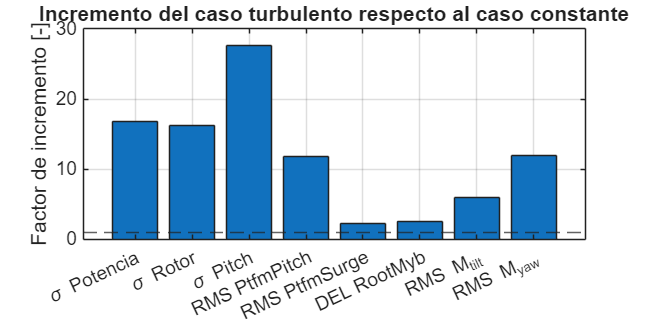


%% ============================================================
% FIGURA 8: incremento relativo del caso turbulento frente al constante
% ============================================================

ratioNames = categorical({ ...
    '\sigma Potencia', ...
    '\sigma Rotor', ...
    '\sigma Pitch', ...
    'RMS PtfmPitch', ...
    'RMS PtfmSurge', ...
    'DEL RootMyb', ...
    'RMS M_{tilt}', ...
    'RMS M_{yaw}'});

ratioNames = reordercats(ratioNames, { ...
    '\sigma Potencia', ...
    '\sigma Rotor', ...
    '\sigma Pitch', ...
    'RMS PtfmPitch', ...
    'RMS PtfmSurge', ...
    'DEL RootMyb', ...
    'RMS M_{tilt}', ...
    'RMS M_{yaw}'});

ratios = [
    tablaBase.Std_GenPwr_MW(2)        / tablaBase.Std_GenPwr_MW(1)
    tablaBase.Std_RotSpeed_rpm(2)     / tablaBase.Std_RotSpeed_rpm(1)
    tablaBase.Std_BldPitch_deg(2)     / tablaBase.Std_BldPitch_deg(1)
    tablaBase.RMS_PtfmPitch_deg(2)    / tablaBase.RMS_PtfmPitch_deg(1)
    tablaBase.RMS_PtfmSurge_m(2)      / tablaBase.RMS_PtfmSurge_m(1)
    tablaBase.DEL_RootMyb_mean_MNm(2) / tablaBase.DEL_RootMyb_mean_MNm(1)
    tablaBase.RMS_Mtilt_MNm(2)        / tablaBase.RMS_Mtilt_MNm(1)
    tablaBase.RMS_Myaw_MNm(2)         / tablaBase.RMS_Myaw_MNm(1)
];

fig = figure('Color','w','Position',[100 100 1100 550]);

bar(ratioNames, ratios);
grid on; box on;
ylabel('Factor de incremento [-]');
title('Incremento del caso turbulento respecto al caso constante');
yline(1, '--');
xtickangle(25);

guardarFigura(fig, outFigDir, 'base_v2_incremento_turbulento_vs_constante');

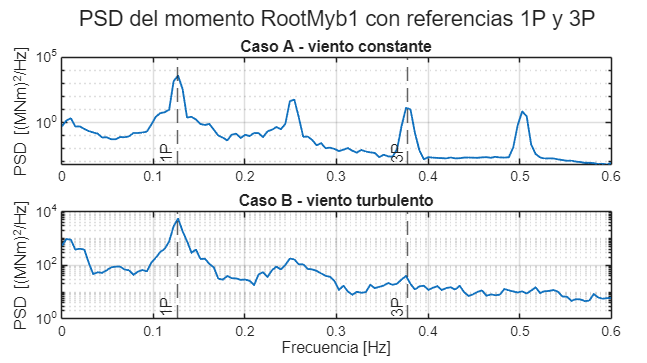


%% ============================================================
% FIGURA 9: PSD semilogarítmica RootMyb1 con 1P y 3P
% ============================================================

fig = figure('Color','w','Position',[100 100 1250 700]);
tl = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

ax = gobjects(2,1);

for i = 1:numel(S)

    ax(i) = nexttile;

    x = S(i).RootMyb1_MNm - mean(S(i).RootMyb1_MNm, 'omitnan');
    fs = 1 / median(diff(S(i).t));

    nwin = round(200 * fs);
    nwin = min(nwin, numel(x));
    noverlap = round(0.5 * nwin);
    nfft = max(2^nextpow2(nwin), 4096);

    [Pxx, f] = pwelch(x, hamming(nwin), noverlap, nfft, fs);

    Pxx(Pxx <= 0) = NaN;

    semilogy(f, Pxx, 'LineWidth', 1.1); hold on;

    f1P = mean(S(i).RotSpeed_rpm, 'omitnan') / 60;
    f3P = 3 * f1P;

    xline(f1P, '--', '1P', ...
        'LabelVerticalAlignment','bottom', ...
        'LabelHorizontalAlignment','left');

    xline(f3P, '--', '3P', ...
        'LabelVerticalAlignment','bottom', ...
        'LabelHorizontalAlignment','left');

    grid on; box on;
    xlim([0 0.6]);
    ylabel('PSD [(MNm)^2/Hz]');
    title(S(i).nombre);
end

xlabel('Frecuencia [Hz]');
title(tl, 'PSD del momento RootMyb1 con referencias 1P y 3P');

guardarFigura(fig, outFigDir, 'base_v2_psd_rootmyb1_semilog');


fprintf('\nFiguras versión 2 guardadas en:\n%s\n', outFigDir);


Figuras versión 2 guardadas en:
C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Figuras_Memoria\Base_v2



%% ============================================================
% FUNCIONES AUXILIARES
% ============================================================

function S = leerCasoOpenFAST(fileOutb, nombreCaso, tTrans)

    [data, chanNames, ~] = ReadFASTbinary(fileOutb);

    if ischar(chanNames)
        chanNames = string(cellstr(chanNames));
    else
        chanNames = string(chanNames);
    end

    chanNames = strtrim(chanNames);
    cleanNames = matlab.lang.makeValidName(chanNames);

    get = @(name) getChannel(data, cleanNames, name);

    S.nombre = char(nombreCaso);

    t = get('Time');

    idx = t >= tTrans;

    S.t = t(idx);

    S.GenPwr_MW = get('GenPwr');
    S.GenPwr_MW = S.GenPwr_MW(idx);

    if mean(abs(S.GenPwr_MW), 'omitnan') > 1000
        S.GenPwr_MW = S.GenPwr_MW / 1000;
    end

    S.RotSpeed_rpm = get('RotSpeed');
    S.RotSpeed_rpm = S.RotSpeed_rpm(idx);

    S.BldPitch1_deg = get('BldPitch1');
    S.BldPitch2_deg = get('BldPitch2');
    S.BldPitch3_deg = get('BldPitch3');

    S.BldPitch1_deg = S.BldPitch1_deg(idx);
    S.BldPitch2_deg = S.BldPitch2_deg(idx);
    S.BldPitch3_deg = S.BldPitch3_deg(idx);

    S.BldPitchMean_deg = mean([ ...
        S.BldPitch1_deg, ...
        S.BldPitch2_deg, ...
        S.BldPitch3_deg], 2, 'omitnan');

    S.PtfmPitch_deg = get('PtfmPitch');
    S.PtfmSurge_m   = get('PtfmSurge');

    S.PtfmPitch_deg = S.PtfmPitch_deg(idx);
    S.PtfmSurge_m   = S.PtfmSurge_m(idx);

    S.Azimuth_deg = get('Azimuth');
    S.Azimuth_deg = S.Azimuth_deg(idx);

    S.RootMyb1_MNm = get('RootMyb1');
    S.RootMyb2_MNm = get('RootMyb2');
    S.RootMyb3_MNm = get('RootMyb3');

    S.RootMyb1_MNm = S.RootMyb1_MNm(idx);
    S.RootMyb2_MNm = S.RootMyb2_MNm(idx);
    S.RootMyb3_MNm = S.RootMyb3_MNm(idx);

    if mean(abs(S.RootMyb1_MNm), 'omitnan') > 1000
        S.RootMyb1_MNm = S.RootMyb1_MNm / 1000;
        S.RootMyb2_MNm = S.RootMyb2_MNm / 1000;
        S.RootMyb3_MNm = S.RootMyb3_MNm / 1000;
    end

    psi = deg2rad(S.Azimuth_deg);

    S.Mtilt_MNm = (2/3) .* ( ...
        S.RootMyb1_MNm .* cos(psi) + ...
        S.RootMyb2_MNm .* cos(psi + 2*pi/3) + ...
        S.RootMyb3_MNm .* cos(psi + 4*pi/3));

    S.Myaw_MNm = (2/3) .* ( ...
        S.RootMyb1_MNm .* sin(psi) + ...
        S.RootMyb2_MNm .* sin(psi + 2*pi/3) + ...
        S.RootMyb3_MNm .* sin(psi + 4*pi/3));
end

function y = getChannel(data, cleanNames, name)

    nameClean = matlab.lang.makeValidName(name);

    idx = find(strcmpi(cleanNames, nameClean), 1);

    if isempty(idx)
        error('No se encuentra el canal: %s', name);
    end

    y = data(:, idx);
end

function y = demeanSignal(x)

    y = x - mean(x, 'omitnan');
end

function y = rmsDemean(x)

    x = x - mean(x, 'omitnan');
    y = sqrt(mean(x.^2, 'omitnan'));
end

function DEL = calcDEL(x, m, Neq)

    x = x(:);
    x = x - mean(x, 'omitnan');

    rf = rainflow(x);

    if istable(rf)
        ranges = rf.Range;
        counts = rf.Count;
    else
        counts = rf(:,1);
        ranges = rf(:,2);
    end

    DEL = (sum(counts .* ranges.^m, 'omitnan') / Neq)^(1/m);
end

function lim = paddedLim(x, padFrac)

    x = x(:);
    x = x(isfinite(x));

    xmin = min(x);
    xmax = max(x);

    if xmin == xmax
        dx = max(abs(xmin), 1) * 0.1;
    else
        dx = xmax - xmin;
    end

    lim = [xmin - padFrac*dx, xmax + padFrac*dx];
end

function lim = symmetricLim(x, padFrac)

    x = x(:);
    x = x(isfinite(x));

    xmax = max(abs(x));

    if xmax == 0
        xmax = 1;
    end

    xmax = xmax * (1 + padFrac);

    lim = [-xmax, xmax];
end

function guardarFigura(fig, outDir, name)

    exportgraphics(fig, fullfile(outDir, [name '.png']), 'Resolution', 300);
    savefig(fig, fullfile(outDir, [name '.fig']));
end